## Gurobi: general Pareto front and time benchmarking

### Uniform weights, step 0.1, alpha=25 (penalty factor)

% Span for uniform weights
span = 0.01:0.02:0.99;

% Placeholders for costs and runtimes
cost_gurobi = zeros(length(span), 2);
runtime_gurobi = zeros(1, length(span));
cost_sedumi = zeros(length(span), 2);
runtime_sedumi = zeros(1, length(span));

% Penalty
alpha = 25;

% Load the network into the workspace
network = network_init();

Not enough input arguments.

Error in network_init (line 3)
if Nconv > 10

% Run computations for one network, different weights

for i = 1:length(span)
    w2 = span(i);
    w1 = 1 - w2;
    network.c = w1 * (network.c1 + alpha * network.cpen) + w2 * network.c2;
    network.Q_biobj = network.Q * w1;
    result_gurobi = solve_gurobi(network);
    [cost_gurobi(i, 1), cost_gurobi(i, 2)] = objective_values(network, alpha, result_gurobi.x);
    runtime_gurobi(i) = result_gurobi.runtime;

    [result_sedumi, runtime_sedumi(i)] = solve_sedumi_alt(network);
    [cost_sedumi(i, 1), cost_sedumi(i, 2)] = objective_values(network, alpha, result_sedumi);
end

gurobi_color = [146 36 40] / 255;
sedumi_color = [57 106 177] / 255;


% Tiles for plot
tiledlayout(2,1);

% Pareto front
nexttile
loglog(cost_gurobi(:, 1), cost_gurobi(:, 2), 'o', 'Color', gurobi_color, 'MarkerSize', 3); hold on
loglog(cost_sedumi(:, 1), cost_sedumi(:, 2), 'o', 'Color', sedumi_color, 'MarkerSize', 3); hold off
title('Pareto Frontiers');
legend('Gurobi', 'SeDuMi');
xlabel('$F_1$, \$', 'Interpreter','latex');
ylabel('$F_2$, MWh', 'Interpreter','latex');
% Move to the next plot tile
nexttile
plot(1:1:length(runtime_gurobi), runtime_gurobi, 'Color', gurobi_color); hold on
plot(1:1:length(runtime_sedumi), runtime_sedumi, 'Color', sedumi_color); hold off
title('Runtimes');
legend('Gurobi', 'SeDuMi');
xlabel('$i$', 'Interpreter','latex');
ylabel('$t$, seconds', 'Interpreter','latex');

% Find the biggest gap in the Pareto front
% Euclidian distance
distances = sqrt(diff(cost_gurobi(:, 1)).^2 + diff(cost_gurobi(:, 2)).^2);

% Find the index of the maximum distance
[~, maxdist] = max(distances);

% Find the corresponding values in the span
upper = span(maxdist);
lower = span(maxdist + 1);

% Construct refinement
span_refined = upper:0.0001:lower;

% Placeholder for front refinement
cost_gurobi_refined = zeros(length(span_refined), 2);

% Compute for new span
for i = 1:length(span_refined)
    w2 = span_refined(i);
    w1 = 1 - w2;
    network.c = w1 * (network.c1 + alpha * network.cpen) + w2 * network.c2;
    network.Q_biobj = network.Q * w1;
    result_gurobi = solve_gurobi(network);
    [cost_gurobi_refined(i, 1), cost_gurobi_refined(i, 2)] = objective_values(network, alpha, result_gurobi.x);
end

figure();
loglog(cost_gurobi(:, 1), cost_gurobi(:, 2), 'o', 'Color', gurobi_color, 'MarkerSize', 3); hold on
loglog(cost_gurobi_refined(:, 1), cost_gurobi_refined(:, 2), 'o', 'Color', 'red', 'MarkerSize', 3); hold off
title('Refined Pareto front');
legend('Original', 'Refinement');
xlabel('$F_1$, \$', 'Interpreter','latex');
ylabel('$F_2$, MWh', 'Interpreter','latex');

## Gurobi: influence of penalty

% Span for uniform weights
span_pen = 0.01:0.01:0.999;
% Span for penalties
pens = [0, 25, 250];

% Placeholder variables
cost_gurobi_pen = zeros(length(span), 2);


% Plot graph in process
tiledlayout(length(pens), 1)

% Do a full front for every penalty
for i = 1:length(pens)
    alpha = pens(i);
    for j = 1:length(span_pen)
        w2 = span_pen(j);
        w1 = 1 - w2;
        network.c = w1 * (network.c1 + alpha * network.cpen) + w2 * network.c2;
        network.Q_biobj = network.Q * w1;
        result_gurobi = solve_gurobi(network);
        [cost_gurobi_pen(j, 1), cost_gurobi_pen(j, 2)] = objective_values(network, alpha, result_gurobi.x);
    end  
    nexttile
    loglog(cost_gurobi_pen(:, 1), cost_gurobi_pen(:, 2), 'o', 'MarkerSize', 3)
end

## Wind and solar generation plots (24H)

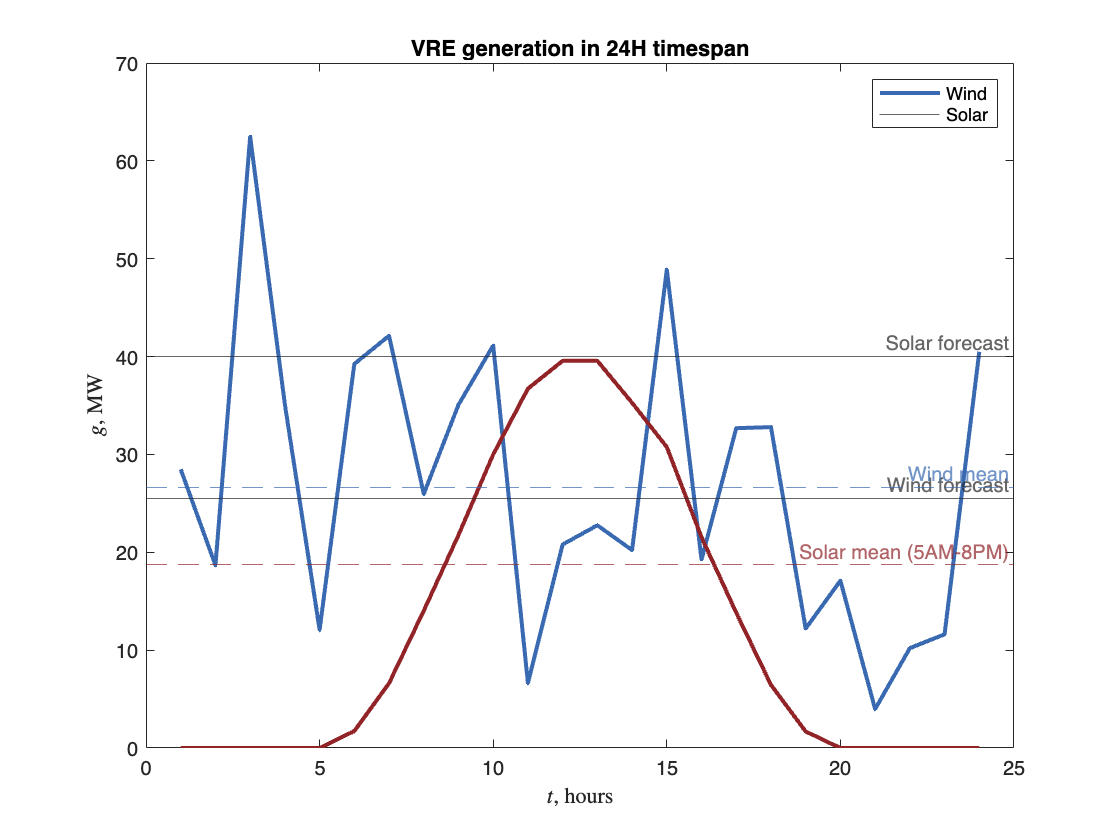

gurobi_color = [146 36 40] / 255;
sedumi_color = [57 106 177] / 255;

x = linspace(1, 24, 24);
wind_power = zeros(1, 24);
solar_power = zeros(1, 24);
for t = 1:24
    wind_power(t) = pdf(t, "wind");
    solar_power(t) = pdf(t, "solar");
end

figure()
plot(x, wind_power, Color=sedumi_color, LineWidth=2); hold on
yline(25.5,'-','Wind forecast');
yline(mean(wind_power),'--','Wind mean', Color=sedumi_color);
plot(x, solar_power, Color=gurobi_color, LineWidth=2); hold off
yline(40,'-','Solar forecast');
yline(mean(solar_power(5:20)),'--','Solar mean (5AM-8PM)', Color=gurobi_color);
title('VRE generation in 24H timespan')
legend('Wind', 'Solar');
xlabel('$t$, hours', 'Interpreter','latex');
ylabel('$g$, MW', 'Interpreter','latex');

## Example of network demand

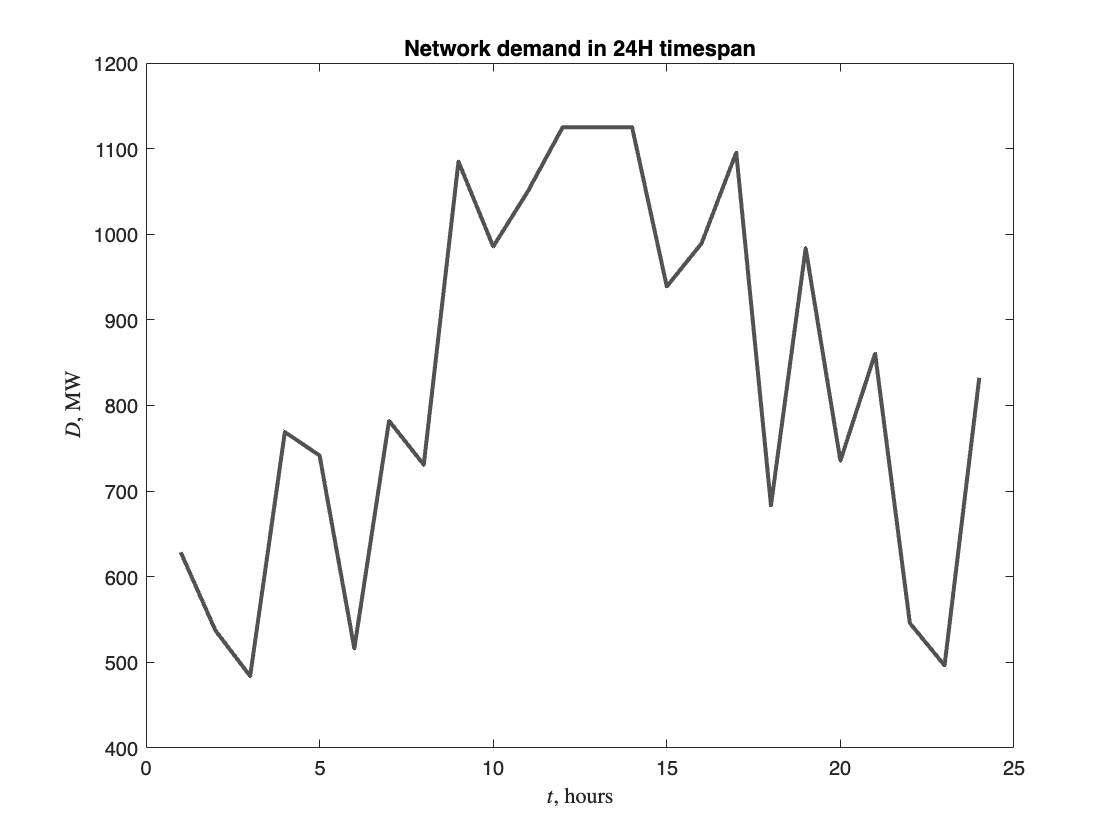

demand_color = [83 81 84]/255;

maxgen = [455, 455, 160, 55];
x = linspace(1, 24, 24);
demand_profile = demand(sum(maxgen), 24);

figure()
plot(x, demand_profile, LineWidth=2, Color=demand_color);
title('Network demand in 24H timespan')
xlabel('$t$, hours', 'Interpreter','latex');
ylabel('$D$, MW', 'Interpreter','latex');